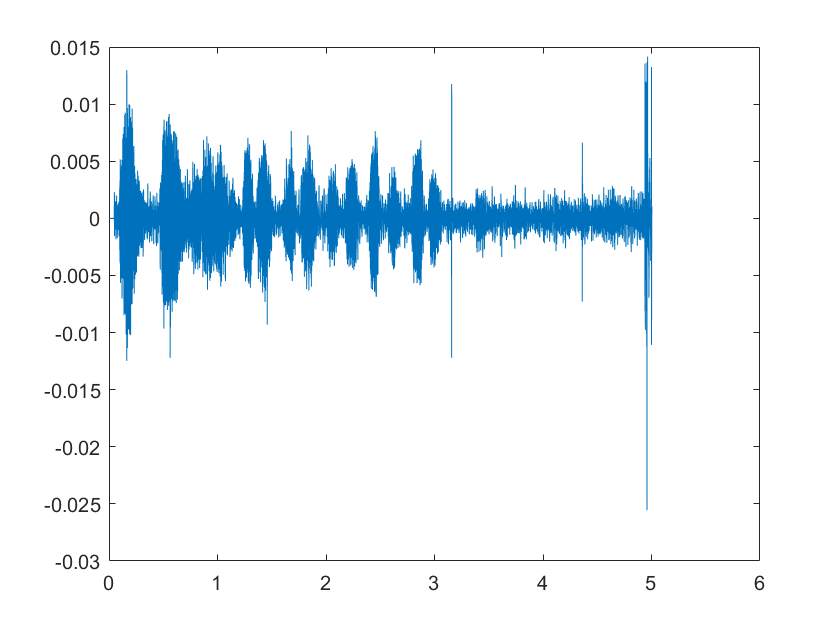

clc;clear; 

[ref1,fs1]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC431196 - Bar-headed Goose - Anser indicus.mp3');
[ref2,fs2]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\bat-noises.mp3');
[ref3,fs3]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\cow.mp3');
[ref4,fs4]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\elephant.mp3');
[ref5,fs5]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\parrot_ref.aac');
[ref6,fs6]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\classic goat.mp3');
[ref7,fs7]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC369151 - Lesser Whistling Duck - Dendrocygna javanica.mp3');
[ref8,fs8]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC569020 - Snow Partridge - Lerwa lerwa.mp3');
%[y_in,fs]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC569020 - Snow Partridge - Lerwa lerwa.mp3'); 
% [ref9,fs9]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC114233 - Indian Spot-billed Duck - Anas poecilorhyncha.mp3');
%[ref9,fs9]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\elephant8.mp3')
[ref9,fs9]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\parrot_sounds_short.wav');

%doc fft
%doc audioread
%length(ref1)
t=0:1/fs1:(length(ref1)-1)/fs1;
ref=ref1(:,1);
ref=ref';
plot(t,ref);

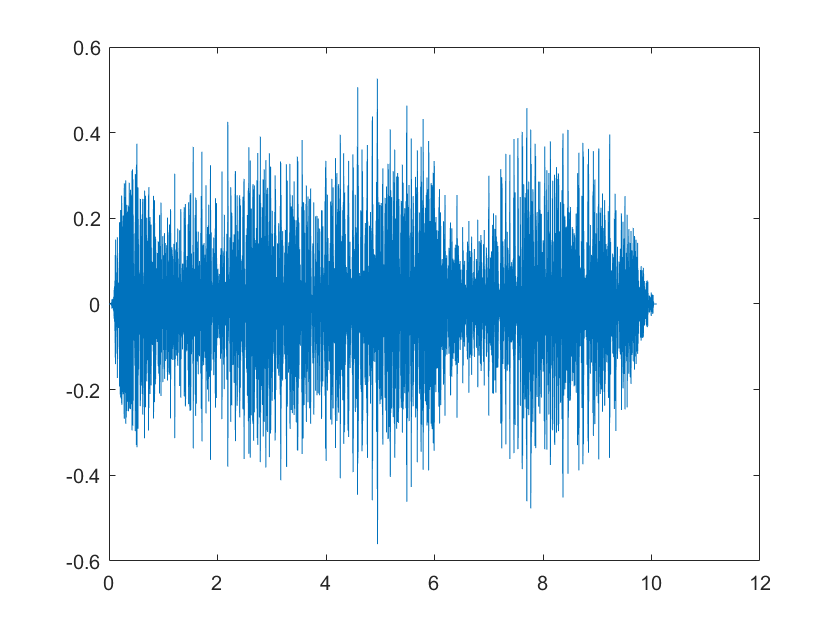


t=0:1/fs2:(length(ref2)-1)/fs2;
ref=ref2(:,1);
ref=ref';
plot(t,ref);

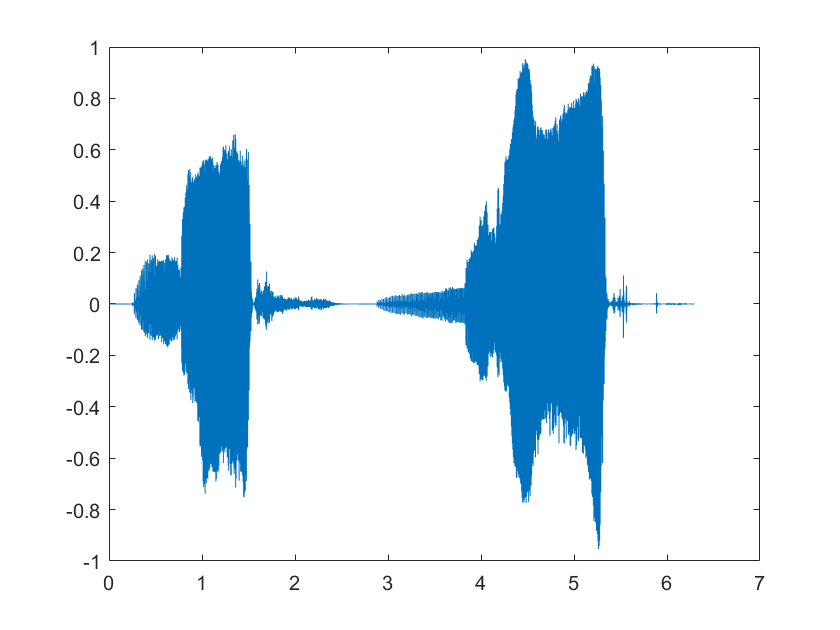


t=0:1/fs3:(length(ref3)-1)/fs3;
ref=ref3(:,1);
ref=ref';
plot(t,ref);

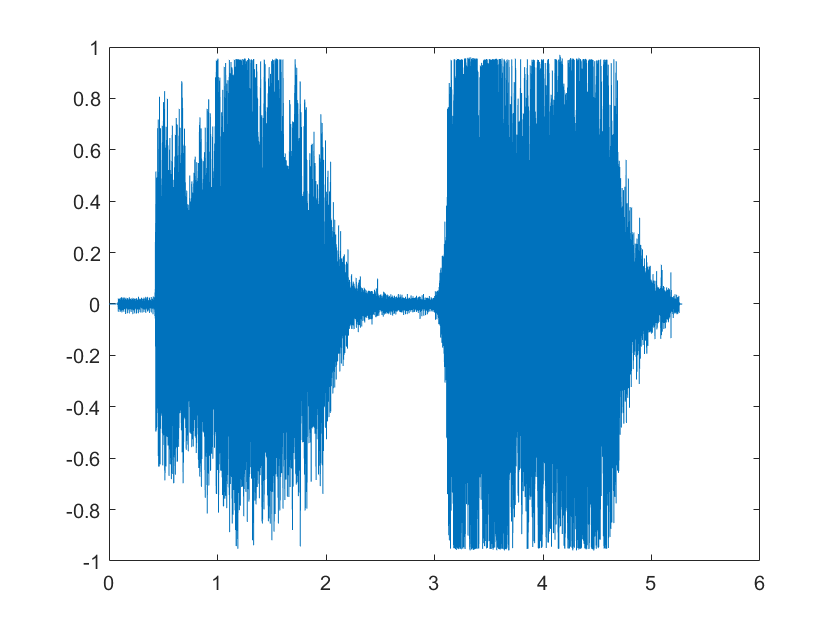


t=0:1/fs4:(length(ref4)-1)/fs4;
ref=ref4(:,1);
ref=ref';
plot(t,ref);

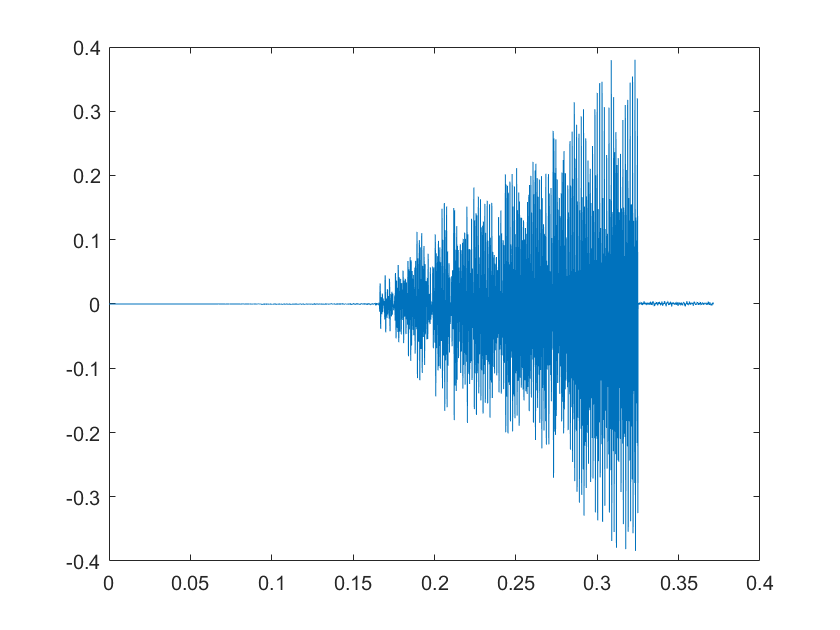


t=0:1/fs5:(length(ref5)-1)/fs5;
ref=ref5(:,1);
ref=ref';
plot(t,ref);

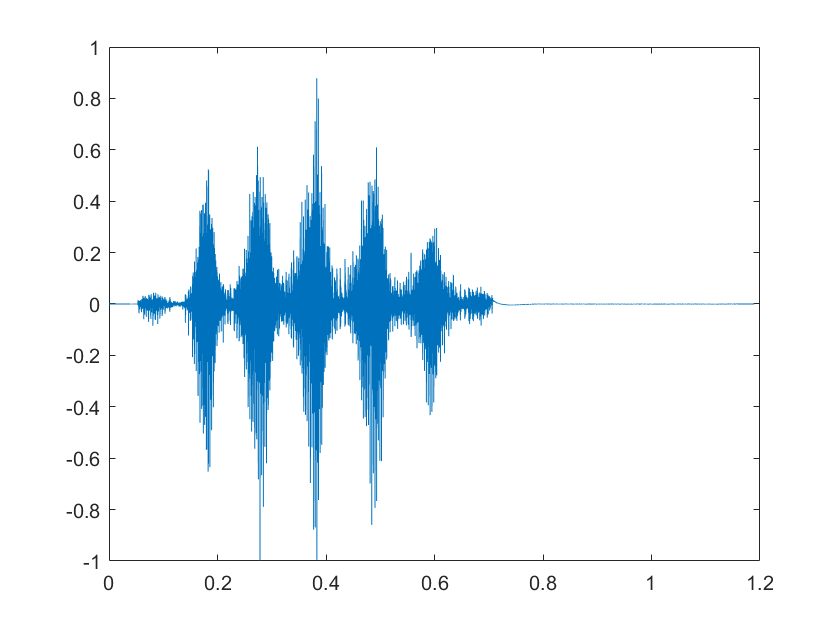


t=0:1/fs6:(length(ref6)-1)/fs6;
ref=ref6(:,1);
ref=ref';
plot(t,ref);

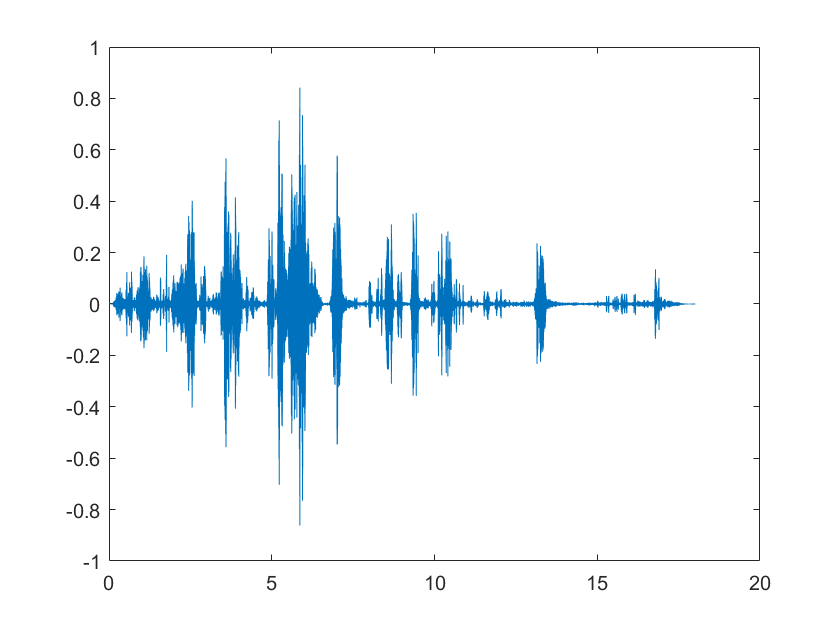


t=0:1/fs7:(length(ref7)-1)/fs7;
ref=ref7(:,1);
ref=ref';
plot(t,ref);

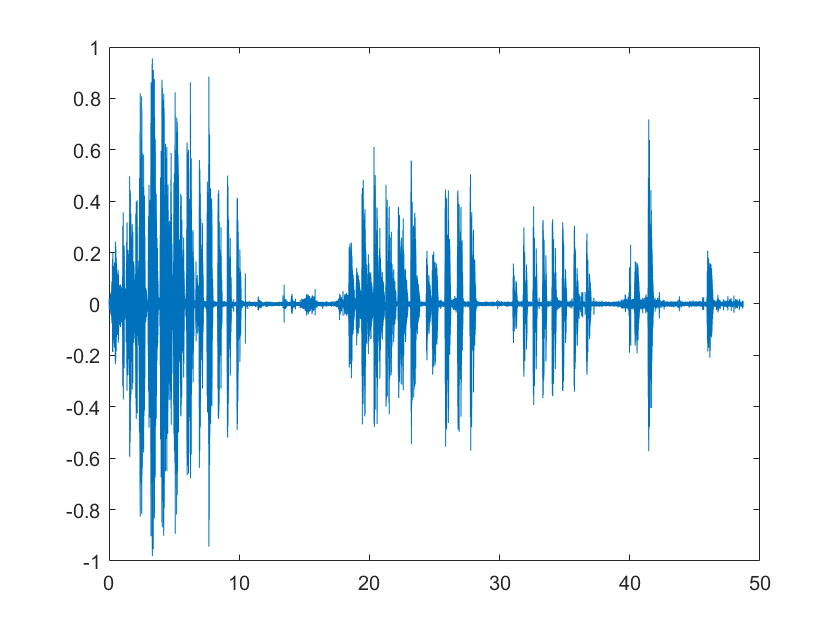


t=0:1/fs8:(length(ref8)-1)/fs8;
ref=ref8(:,1);
ref=ref';
plot(t,ref);

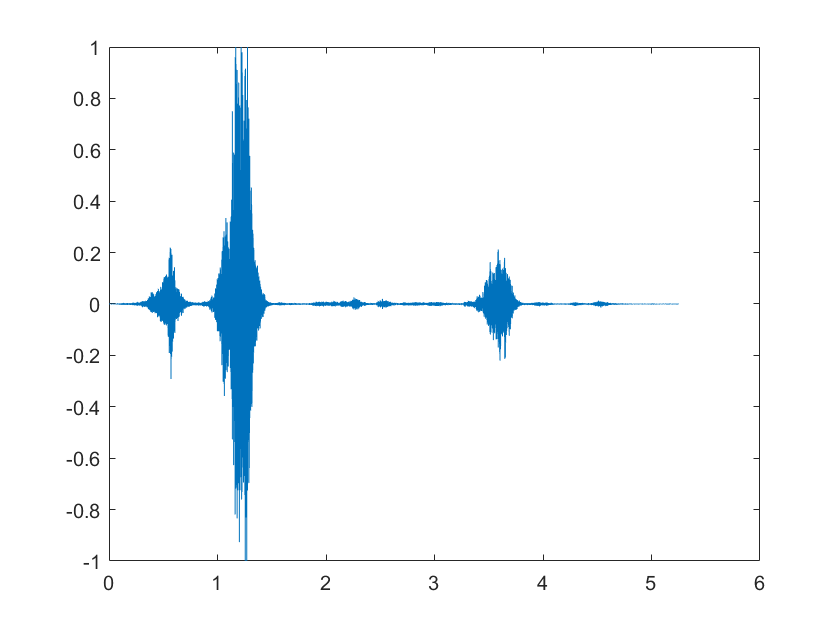


t=0:1/fs9:(length(ref9)-1)/fs9;
ref=ref9(:,1);
ref=ref';
plot(t,ref);



% y=abs(fft(ref));
% f=(0:length(y)-1)*fs1/length(y);
% plot(f,y);

clc;clear; 
[ref1,fs1]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC431196 - Bar-headed Goose - Anser indicus.mp3');
%[ref2,fs2]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\bat-noises.mp3');
[ref2,fs2]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\elephant.mp3');

%resample at 30,000 Hz sampling freq
fsc=30000; %fs_common
[P,Q] = rat(30000/fs1);
ref1 = resample(ref1,P,Q);
ref1=ref1(0.5*fsc:1*fsc,:);
ref1=100*normalize(ref1,'range');

[P,Q] = rat(30000/fs2);
ref2 = resample(ref2,P,Q);
ref2=ref2(1*fsc:1.5*fsc,:);
ref2=100*normalize(ref2,'range');

Y1=abs(fft(ref1));
Y2=abs(fft(ref2));


[corr_seq1 lags1] =xcorr(Y1(:,1),Y1(:,1));
corr_seq1(lags1==0)

ans = 7.7787e+11


[corr_seq2 lags2] =xcorr(Y2(:,1),Y1(:,1));
corr_seq2(lags2==0)

ans = 6.5290e+11